# Continuation of quasiperiodic invariant tori (continued)

We consider Van der Pol oscillator subject to harmonic excitation as follows


$$\ddot{x}-c(1-x^2)\dot{x}+x=a\cos\Omega t$$


and we are interested in the quasiperiodic response of such a system. Here we perform

- continuation of periodic orbits with varied $\Omega$ and detect TR bifurcation point,

- continuation of TR points with varied $a$ and $\Omega$,

- continuation of tori using **ode_TR2tor **with a TR point as starting point

## Construct initial periodic orbit

% Construct an initial solution
% pnames = [  om     c     a ]
p0 = [ 1.0; 0.11; 0.2 ];
T  = 2*pi/p0(1);
[~,x0] = ode45(@(t,x) vdp(t,x,p0), 0:100*T, [0; 0]); % Approximate periodic orbit of reduced system
[t0,x0] = ode45(@(t,x) vdp(t,x,p0), linspace(0,T,100), x0(end,:));


## Continuation of periodic orbit

prob = coco_prob();
prob = coco_set(prob, 'ode', 'autonomous', false);
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'h_max', 5);
prob = coco_set(prob, 'coll', 'NTST', 20);
prob = ode_isol2po(prob, '', @vdp, @vdp_DFDX, @vdp_DFDP, @vdp_DFDT,... 
  t0, x0, {'Om2','c','a'}, p0);
[data, uidx] = coco_get_func_data(prob, 'po.orb.coll', 'data', 'uidx');
maps = data.coll_seg.maps;
prob = coco_add_func(prob, 'OmegaT', @OmegaT, @OmegaT_du, [], 'zero',...
    'uidx', [uidx(maps.T_idx), uidx(maps.p_idx(1))]);

fprintf('\n Run=''%s'': Continue family of periodic orbits.\n', ...
  'po');


 Run='po': Continue family of periodic orbits.



coco(prob, 'po', [], 1, {'Om2','po.period'}, [0.7 1.3]);


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.74e-01  2.74e+01    0.0    0.0    0.0
   1   1  1.00e+00  5.25e-01  1.12e-03  2.74e+01    0.0    0.0    0.0
   2   1  1.00e+00  7.35e-03  1.94e-07  2.74e+01    0.0    0.0    0.0
   3   1  1.00e+00  2.89e-06  2.66e-14  2.74e+01    0.0    0.0    0.0
   4   1  1.00e+00  3.84e-13  9.05e-15  2.74e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           Om2    po.period
    0  00:00:00   2.7429e+01      1  EP      1.0108e+00   6.2162e+00
   10  00:00:00   2.9453e+01      2          9.9479e-01   6.3161e+00
   20  00:00:01   3.2237e+01      3          9.7162e-01   6.4667e+00
   30  00:00:01   2.8457e+01      4          9.5365e-01   6.5886e+00
   40  00:00:02   2.3194e+01      5          9.4187e-01   6.6709e+00
   48  00:00:03   1.9095e+01      6  TR      9.3156e-01   6.7448e+00
   50  00:00:03   1.8113e

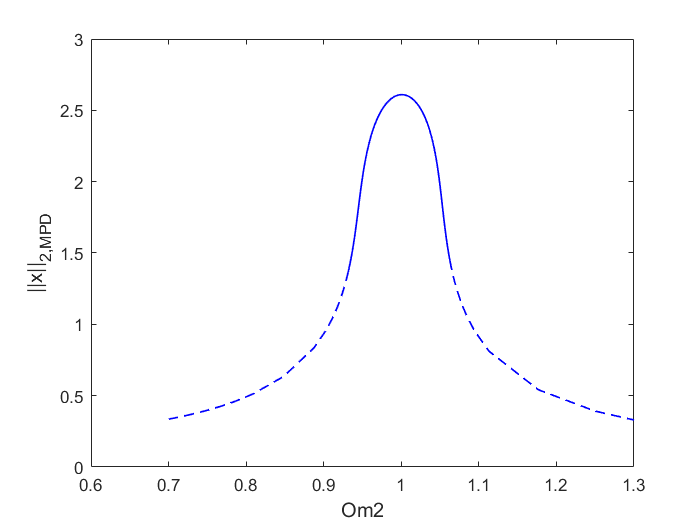


figure; coco_plot_bd('po')

## Continuation of TR points

bd     = coco_bd_read('po');
TRlabs = coco_bd_labs(bd, 'TR');
TRlab  = max(TRlabs);
prob = coco_prob();
prob = coco_set(prob, 'ode', 'autonomous', false);
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'h_max', 5, 'bi_direct', false);
prob = ode_po2TR(prob, '', 'po', TRlab);
[data, uidx] = coco_get_func_data(prob, 'po.orb.coll', 'data', 'uidx');
maps = data.coll_seg.maps;
prob = coco_add_func(prob, 'OmegaT', @OmegaT, @OmegaT_du, [], 'zero',...
    'uidx', [uidx(maps.T_idx), uidx(maps.p_idx(1))]);

fprintf('\n Run=''%s'': Continue family of TR points.\n', ...
  'po_TR');


 Run='po_TR': Continue family of TR points.



coco(prob, 'po_TR', [], 1, {'Om2','po.period','a'}, [1.0 1.5]);


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          3.40e-08  2.32e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           Om2    po.period            a
    0  00:00:00   2.3206e+01      1  EP      1.0623e+00   5.9149e+00   2.0000e-01
   10  00:00:01   2.3141e+01      2          1.1229e+00   5.5956e+00   3.7963e-01
   20  00:00:02   2.3119e+01      3          1.2501e+00   5.0263e+00   8.0209e-01
   28  00:00:03   2.4013e+01      4  EP      1.5000e+00   4.1888e+00   1.7721e+00


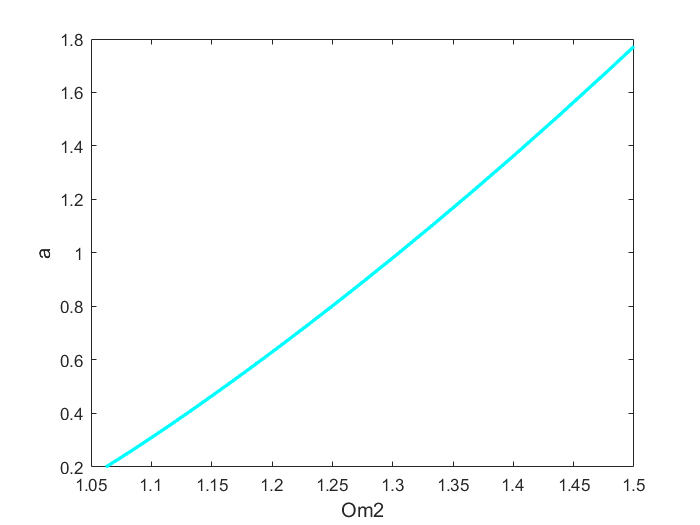

figure;
coco_plot_bd('po_TR','Om2','a')

## Continuation of tori from TR point

bd  = coco_bd_read('po_TR');
lab = coco_bd_labs(bd, 'EP');
lab = max(lab);
prob = coco_prob();
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'PtMX', 100,...
    'h_max', 15, 'bi_direct', false);
prob = coco_set(prob, 'corr', 'ItMX', 20);
prob = coco_set(prob, 'coll', 'NTST', 20);
prob = ode_TR2tor(prob, '', 'po_TR', lab, 'neg', 1e-5);

fprintf(...
  '\n Run=''%s'': Continue torus from point %d in run ''%s''.\n', ...
  'tr1', lab, 'po_TR');


 Run='tr1': Continue torus from point 4 in run 'po_TR'.


coco(prob, 'tr1', [], 1, {'varrho', 'Om2','om2','om1','c','a'},[-0.5,-0.3]);


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          5.02e-02  8.57e+01    0.0    0.0    0.0
   1   1  1.00e+00  2.72e-02  2.85e-07  8.58e+01    0.0    0.1    0.0
   2   1  1.00e+00  4.63e-06  3.11e-14  8.58e+01    0.0    0.2    0.0
   3   1  1.00e+00  4.35e-06  2.98e-14  8.58e+01    0.0    0.3    0.1
   4   1  1.00e+00  1.95e-07  2.94e-14  8.58e+01    0.0    0.4    0.1

 STEP      TIME        ||U||  LABEL  TYPE        varrho          Om2          om2          om1            c            a
    0  00:00:01   8.5752e+01      1  EP     -3.3293e-01   1.5000e+00   1.5000e+00  -4.9939e-01   1.1000e-01   1.7721e+00
   10  00:00:07   8.7622e+01      2         -3.4385e-01   1.5250e+00   1.5250e+00  -5.2437e-01   1.1000e-01   1.7721e+00
   14  00:00:12   9.0321e+01      3  BP     -3.6052e-01   1.5646e+00   1.5646e+00  -5.6405e-01   1.1000e-01   1.7721e+00
   16  00:00:16   9.1219

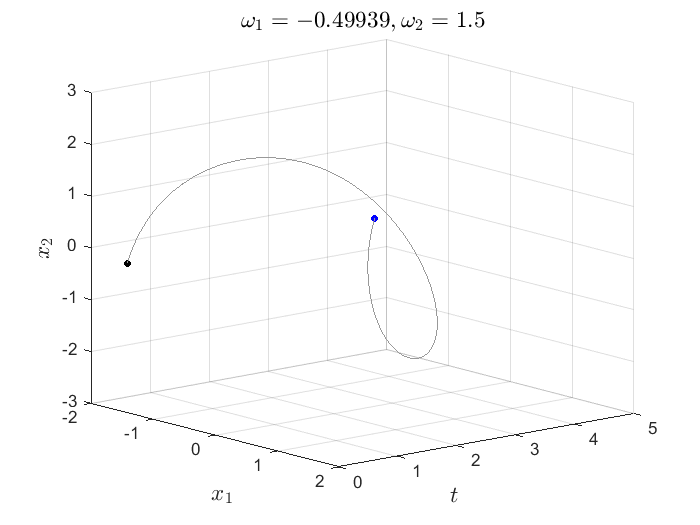

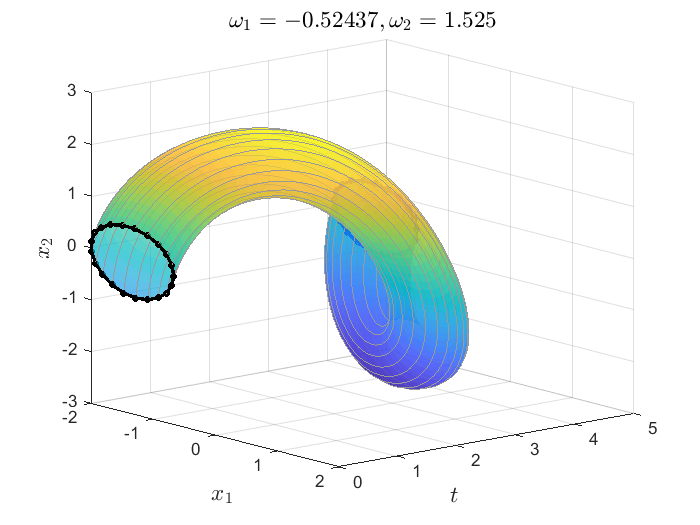

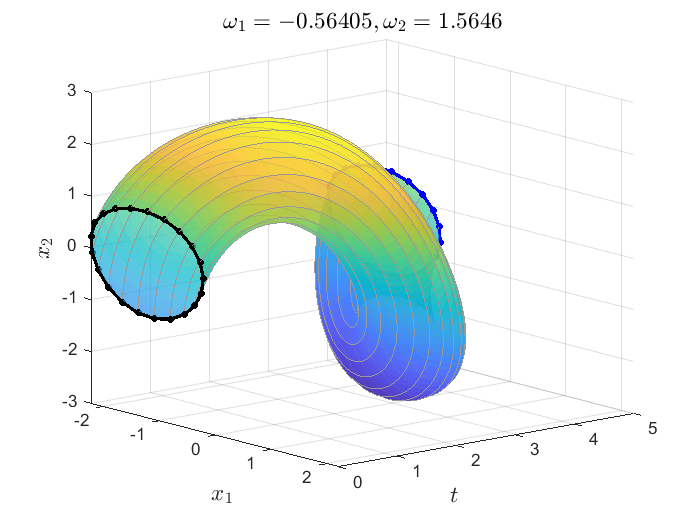

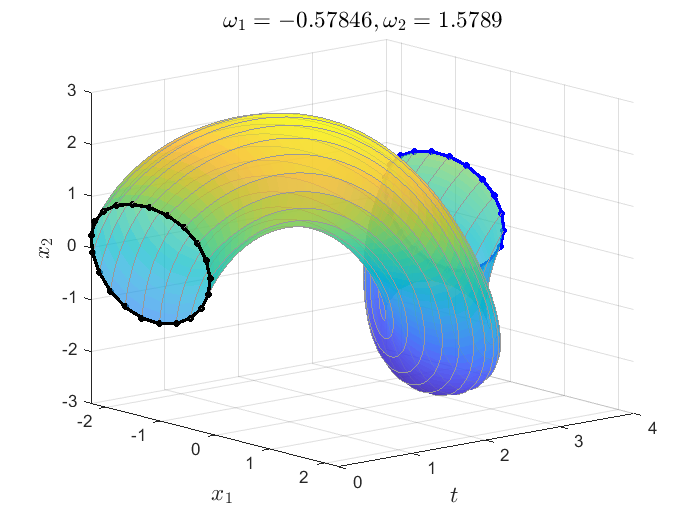

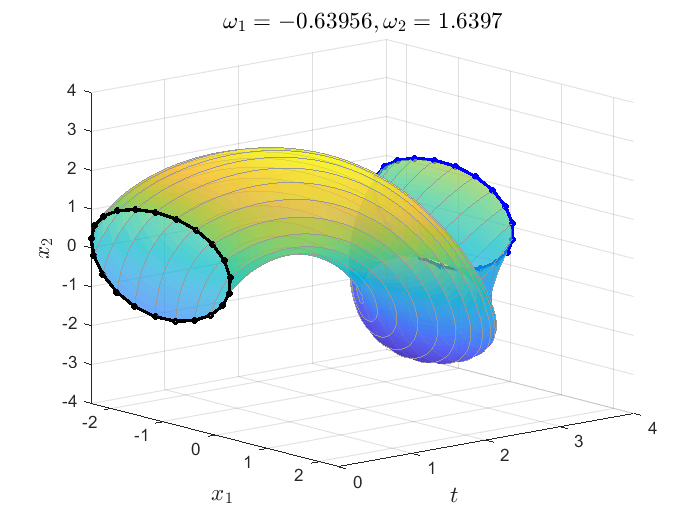

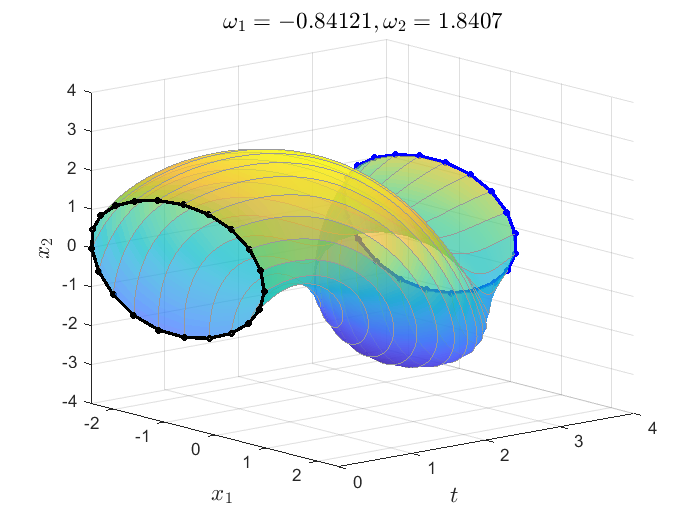

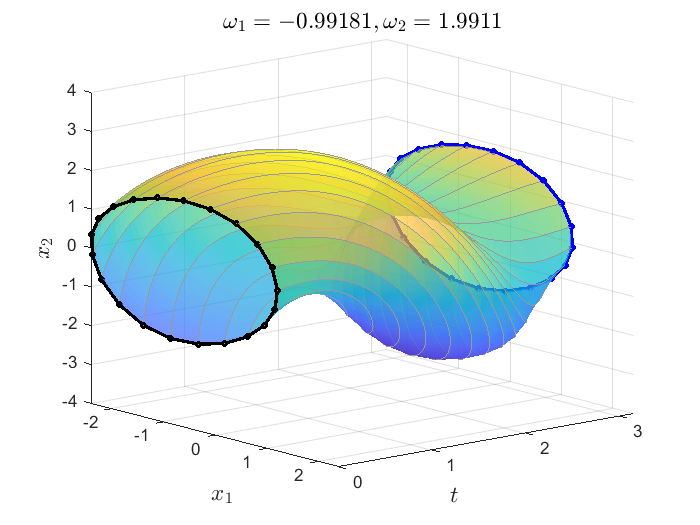

for lab = 1:7
    plot_torus('','tr1',lab, [1 2]); pause(1);
end

## Comparison with numerical integration

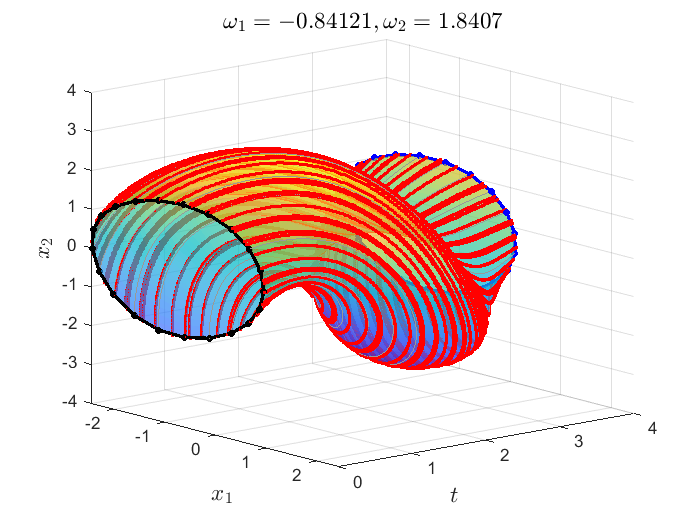

% time integration
lab = 6;
plot_torus('','tr1', lab, [1 2]);hold on
sol = tor_read_solution('','tr1',lab);
p   = sol.p(1:end-3);
xbp = sol.xbp;
T   = 2*pi/sol.p(end-1);
[t,x] = ode45(@(t,x) vdp(t,x,p), 0:0.01:50*T, xbp(1,:,1));
plot3(x(:,1),mod(t,T),x(:,2),'r.');